This script is the 3rd script of a series of live scripts that discuss the problem of background correction.

First I'll generate the population of Ach sensor photons based on empirically collected fitting parameters. Here we will assume the Ach sensor fluorescence follows double exponential decay. 

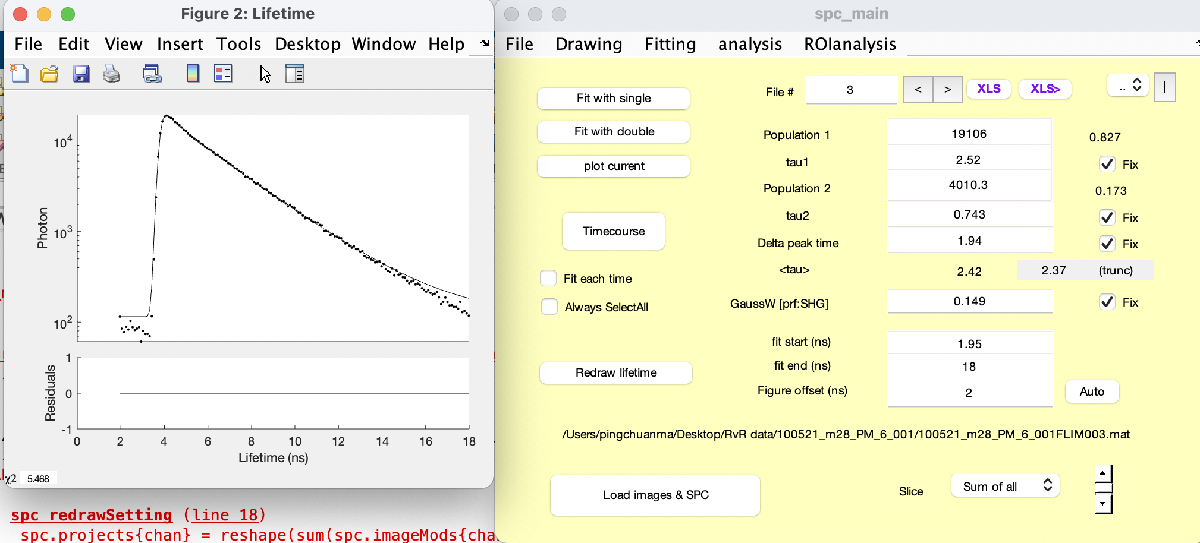

tau1=2.5186; tau2=0.7425; p1=0.8265; p2=0.1735; TP=100000; % Peak photon 100000
GenPop256(TP,p1,p2,tau1,tau2);

'GenPop256' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/pingchuanma/Documents/MATLAB/simulation

Change the MATLAB current folder or add its folder to the MATLAB path.

load('DoubleExpPop256.mat');
save('DoubleExpPop256_1019','Population');

This section is to sample the histograms to mimick empirically collected data from FLIM experiments, with different background.

First I'll sample histograms with different photon sizes, but without any autofluorescence, and after-pulse. Then for each photon size, I'll add different background into each channel of the histograms.

Other data used: 

prf: 

Autofluorescence: 

Photon sizes: 100000, 300000, 600000;

For background adding, I've looked at the background (with or without LED light) information from 2 mice, and decide that without LED, the range of background will be from 1000 to 2000 per second. With LED, the range of background will be from 3000 to 10000.

Therefore, there will be 2 conditions: first, the background is added as a random number between 1000 to 2000; second, the background will be added as a random number between 3000 to 10000.

GeneratedPopulation='DoubleExpPop256_1019'; 
mkdir('back_corr_samples_noAF_do_correction')

filepath='/Users/pingchuanma/Documents/MATLAB/simulation/back_corr_samples_noAF_do_correction';
samplesize=[100000 300000 600000];
for i=1:3
    mkdir([filepath,'/',num2str(samplesize(i))])
    for j=1:100
        FLIMsim256_noauto(samplesize(i),3000,18300, GeneratedPopulation);
        load('FLIMSimulation_pm.mat');
        samplename=[filepath,'/',num2str(samplesize(i)),'/',num2str(j)];
        save(samplename,'n','xout');
    end
end

Next I'll add different amount of background into each channels of the histogram.

filepath='/Users/pingchuanma/Documents/MATLAB/simulation/back_corr_samples_noAF_do_correction';
samplesize=[100000 300000 600000];
for i=1:3
    cd([filepath,'/',num2str(samplesize(i))])
    for j=1:100
        load([num2str(j),'.mat'])
        n1=n+(1000+1000*rand)/256;
        n2=n+(3000+7000*rand)/256;
        samplename1=[num2str(j),'_noLED.mat'];
        samplename2=[num2str(j),'_LED.mat'];
        
        samplename4=[num2str(j),'_0.mat'];
        save(samplename1,'n1');
        save(samplename2,'n2');
        
        save(samplename4,'n');
    end
    
end

Next is doing the fitting.

I'm doing prf fitting, using the exact prf I was using for sampling.

filepath='/Users/pingchuanma/Documents/MATLAB/simulation/back_corr_samples_noAF_do_correction';
samplesize=[100000 300000 600000];
chan=1;
for i=1
    cd([filepath,'/',num2str(samplesize(i))]);
    matfiles_0=dir('*_0.mat');
    matfiles_noLED=dir('*_noLED.mat');
    matfiles_LED=dir('*_LED.mat');
    
    for j=1:100
        filename=matfiles_0(j).name;
        load(filename);
        spc.lifetimes{1,1} = n;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        p1_0(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3);
        avg_tau_fit_0(j)=spc.fits{chan}.avgTau;
        emp_tau_0(j)=spc.fits{1}.EmpTauTrunc;
        chi2_0(j)=spc.fits{chan}.redchisq;
        backcorr_0(j)=spc.fit.backCorr;
    end
    for j=1:100
        filename=matfiles_noLED(j).name;
        load(filename);
        spc.lifetimes{1,1} = n1;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        p1_noLED(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3);
        avg_tau_fit_noLED(j)=spc.fits{chan}.avgTau;
        emp_tau_noLED(j)=spc.fits{1}.EmpTauTrunc;
        chi2_noLED(j)=spc.fits{chan}.redchisq;
        backcorr_noLED(j)=spc.fit.backCorr;
    end
    for j=1:100
        filename=matfiles_LED(j).name;
        load(filename);
        spc.lifetimes{1,1} = n2;
        spc_fitexp2prfGY(1);
        spc_adjustTauOffset(1);
        p1_LED(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3);
        avg_tau_fit_LED(j)=spc.fits{chan}.avgTau;
        emp_tau_LED(j)=spc.fits{1}.EmpTauTrunc;
        chi2_LED(j)=spc.fits{chan}.redchisq;
        backcorr_LED(j)=spc.fit.backCorr;
    end
%     for j=1:100
%         filename=matfiles_100(j).name;
%         load(filename);
%         spc.lifetimes{1,1} = n3;
%         spc_fitexp2prfGY(1);
%         spc_adjustTauOffset(1);
%         p1_100(j)=spc.fits{chan}.beta1/(spc.fits{chan}.beta1+spc.fits{chan}.beta3);
%         avg_tau_fit_100(j)=spc.fits{chan}.avgTau;
%         emp_tau_100(j)=spc.fits{1}.EmpTauTrunc;
%         chi2_100(j)=spc.fits{chan}.redchisq;
%         backcorr_100(j)=spc.fit.backCorr;
%     end
end

fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0


fraction of photons from SHG: 0



SaveResultName=['backcorr_simulation_result_',num2str(i)];
save(SaveResultName,"backcorr_LED","chi2_LED","emp_tau_LED","avg_tau_fit_LED","p1_LED",...
    "backcorr_noLED","chi2_noLED","emp_tau_noLED","avg_tau_fit_noLED","p1_noLED","backcorr_0","chi2_0","emp_tau_0","avg_tau_fit_0","p1_0");


Plotting the results.

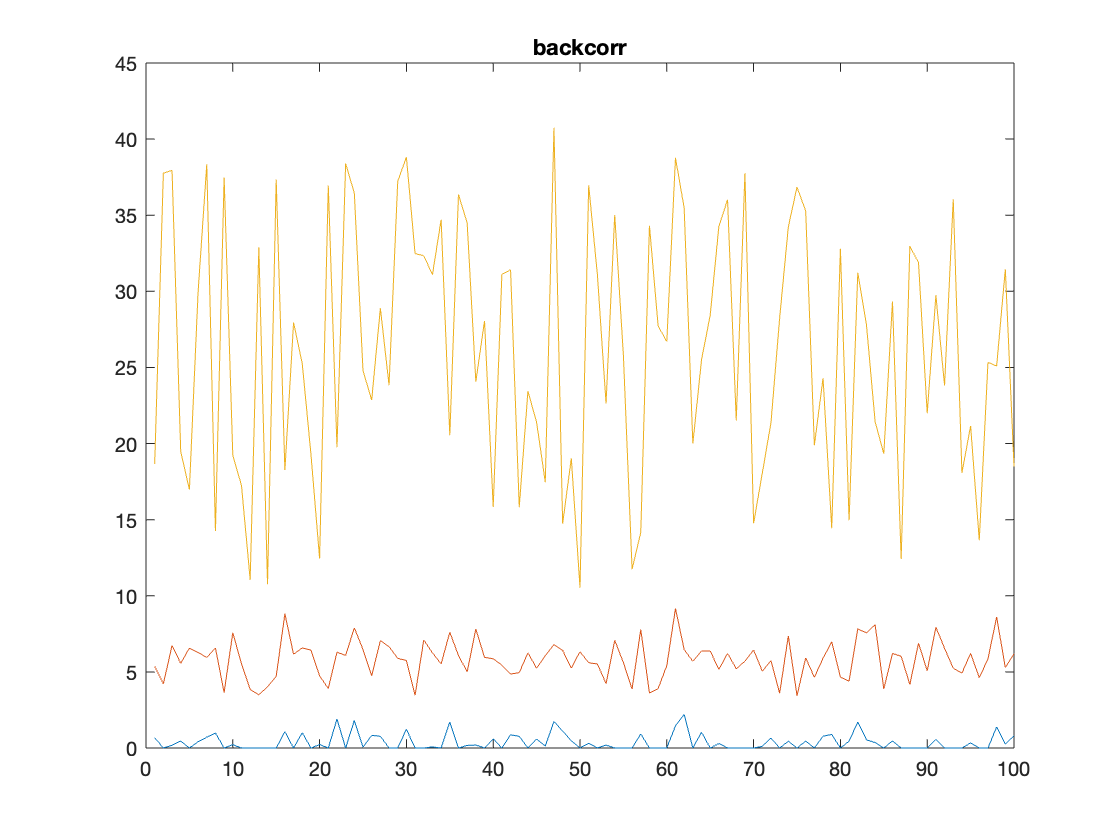

figure
plot(backcorr_0)
hold on
plot(backcorr_noLED)
hold on
plot(backcorr_LED)

title('backcorr')

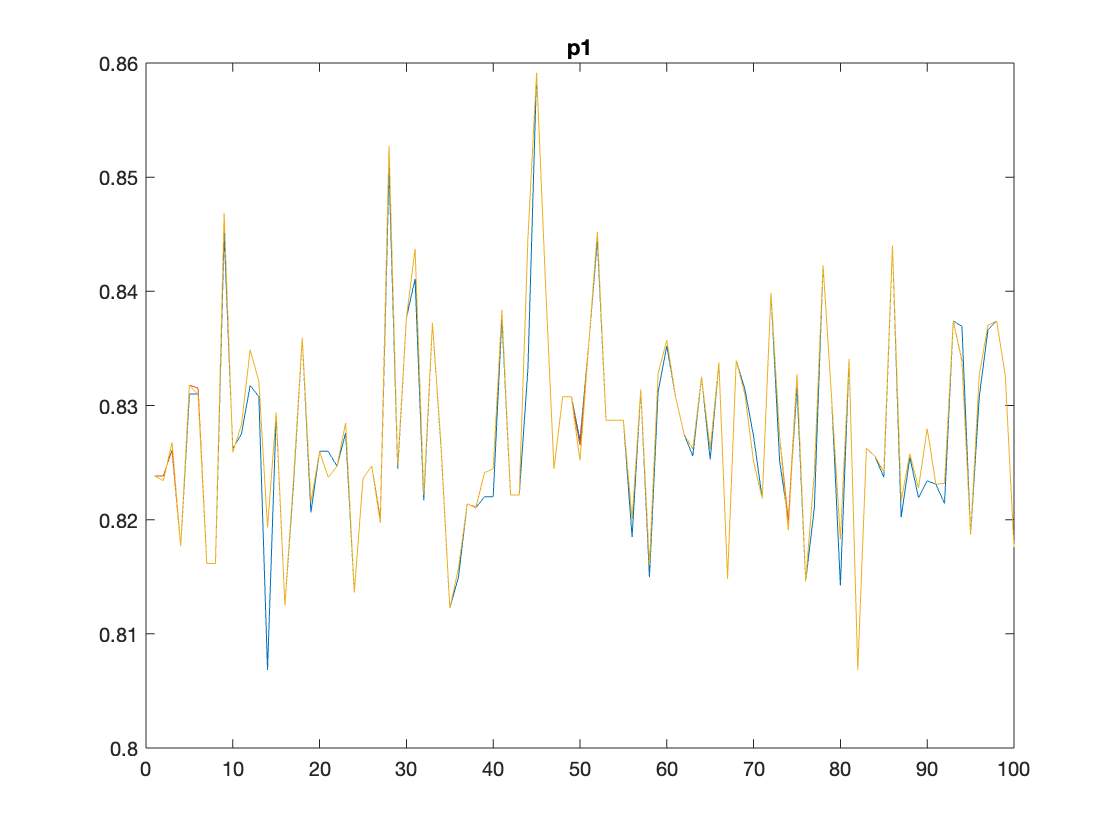


figure
plot(p1_0)
hold on
plot(p1_noLED)
hold on
plot(p1_LED)

title('p1')

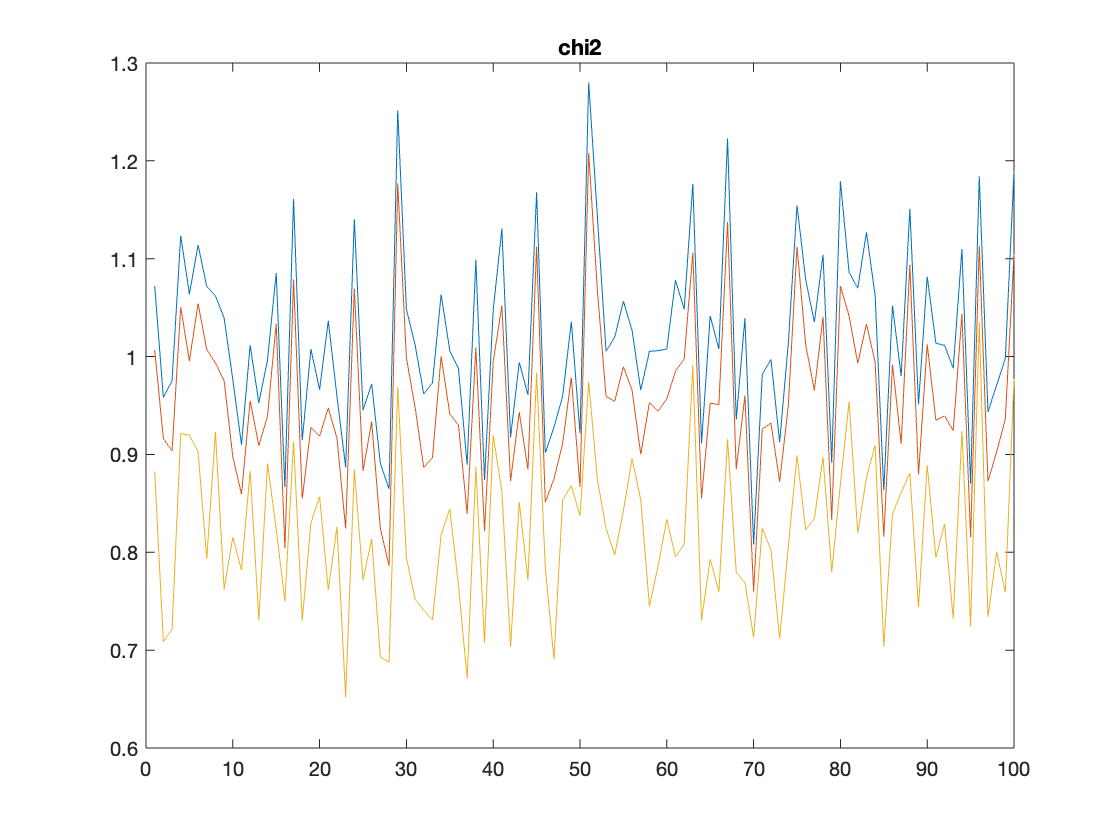


figure
plot(chi2_0)
hold on
plot(chi2_noLED)
hold on
plot(chi2_LED)

title('chi2')

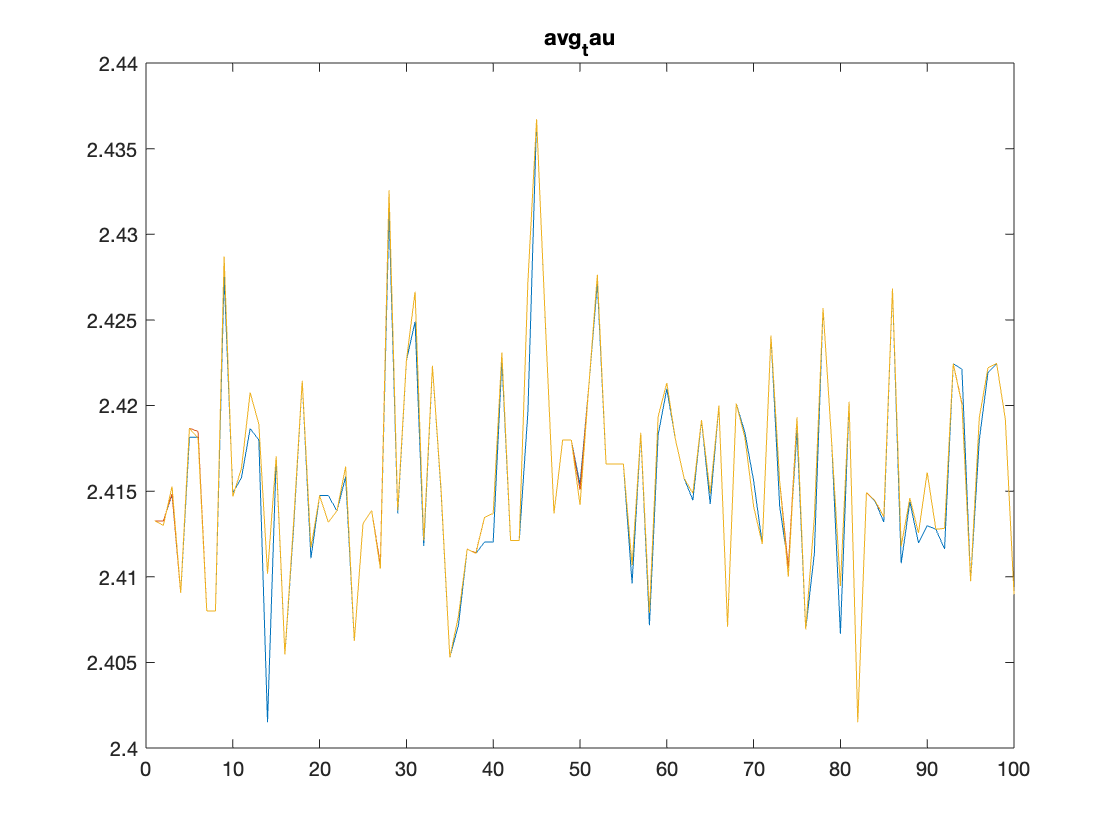


figure
plot(avg_tau_fit_0)
hold on
plot(avg_tau_fit_noLED)
hold on
plot(avg_tau_fit_LED)

title('avg_tau')

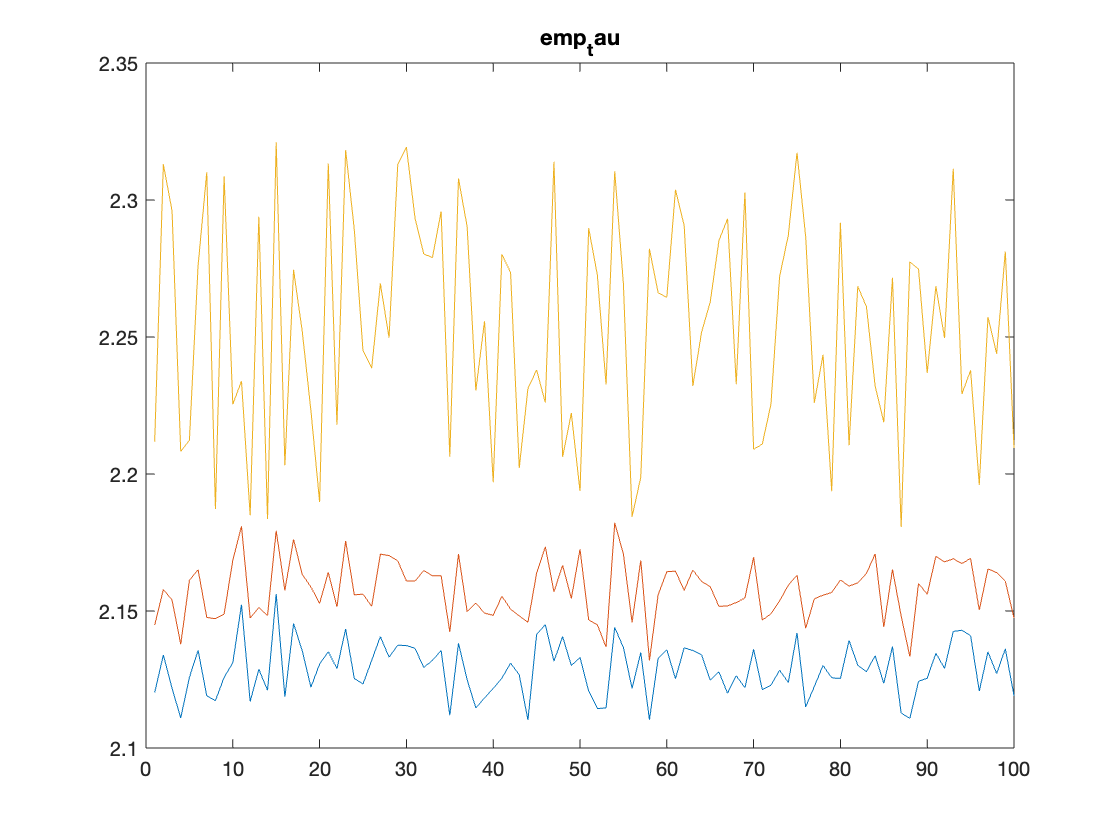



figure
plot(emp_tau_0)
hold on
plot(emp_tau_noLED)
hold on
plot(emp_tau_LED)

title('emp_tau')

It looks like that the program is dealing with the background pretty well.